用误差条形图和散点对两组采样数据进行比较，并显示 t test p 值

## 语法

## 示例

## 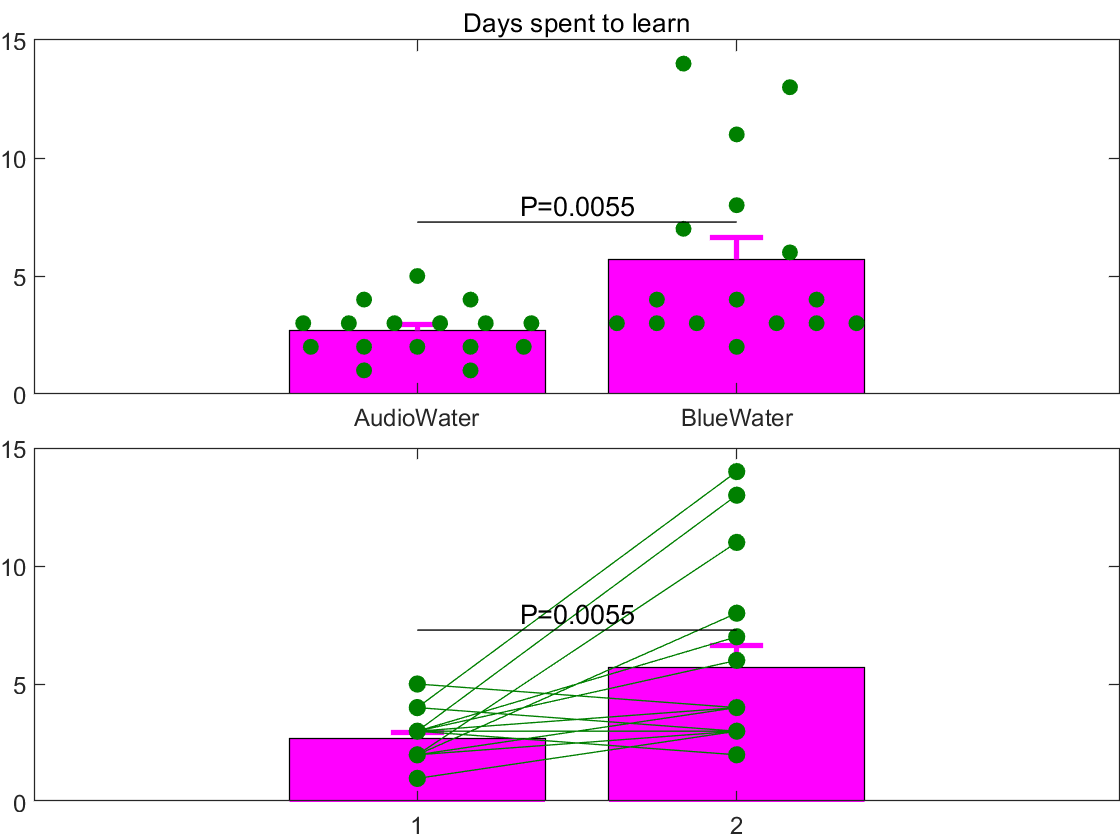

## 输入参数

Data，分组采样数据，可以是：

- 实数矩阵，每组一列。如果显示散点，同一行的散点将被匹配连接起来。每组的条形下方将用数字标识组序数。

- table，每组一列。如果显示散点，同一行的散点将被匹配连接起来。每组的条形下方将用表列名标识组名。

- (1,:)cell，每组一个元胞，元胞里是实数列向量。如果显示散点，将不会匹配连接，而是均匀分布在各个高度上。每组的条形下方将用数字标识组序数。

- (1,1)struct，每组一个字段，字段值是实数列向量。如果显示散点，将不会匹配连接，而是均匀分布在各个高度上。每组的条形下方将用字段名标识组名。

ShowScatter(1,1)logical=true，是否显示散点。

CompareGroup table，分组配对比较表，标识要将哪些分组配对计算P值，每行一对。只有2组时，默认显示P值；多于2组时，默认不显示P值。指定空表table.empty以显式要求不显示任何P值。包含以下列：

- GroupPair(:,2)，必需，为每个比较配对指定要比较的两个分组。如果Data中指定了组名，GroupPair可以指定为字符串；否则只能为组序数。

- PLineOffset(:,1)，可选。为每个配对计算的P值将显示在图上，有时这些显示字符可能发生重叠。使用此参数手动垫高特定配对的P值显示位置，避免与其它P值重叠。

Colors(2,3)double，指定条形和散点的RGB颜色，范围[0,1]。第1行指定条形颜色，第2行指定散点颜色。误差条颜色和条形相同，连接线颜色和样本点相同。

## 返回值

P(1,1)double，所有组的总体P值

MultiCompare(:,2)table，对应CompareGroup，每行一个分组对，包含以下列：

- GroupPair(:,2)，计算P值的分组对。如果Data中包含组名，将用组名表示分组对，否则用组序数。

- PValue，该分组对两两比较的P值

**See also** [ttest2](matlab:doc ttest2)

function [P,MultiCompare]=BarScatterCompare(Data,varargin)
import UniExp.Flags
ShowScatter=true;
CompareGroup=missing;
Colors=[0,0.5,0;1,0,1];
for V=1:nargin
	Arg=varargin{V};
	if islogical(Arg)
		ShowScatter=Arg;
	elseif istabular(Arg)
		CompareGroup=Arg;
	else
		Colors=Arg;
	end
end
if isreal(Data)
	DataType=Flags.Real;
elseif istabular(Data)
	DataType=Flags.Table;
elseif iscell(Data)
	DataType=Flags.Cell;
elseif isstruct(Data)
	DataType=Flags.Struct;
end
switch DataType
	case Flags.Real
		[Mean,Sem]=MATLAB.DataFun.MeanSem(Data,1);
		[NumRepeats,NumGroups]=size(Data);
	case Flags.Table
		[Mean,Sem]=MATLAB.DataFun.MeanSem(Data{:,:},1);
		[NumRepeats,NumGroups]=size(Data);
	case Flags.Cell
		[Mean,Sem]=cellfun(@MATLAB.DataFun.MeanSem,Data);
		NumGroups=numel(Data);
	case Flags.Struct
		[Mean,Sem]=structfun(@MATLAB.DataFun.MeanSem,Data);
		NumGroups=numel(Mean);
end
Xs=(1:NumGroups)';
bar(Mean,FaceColor=Colors(1,:));
switch DataType
	case Flags.Table
		HasGroupNames=true;
		GroupNames=Data.Properties.VariableNames;
		xticklabels(GroupNames);
	case Flags.Struct
		HasGroupNames=true;
		GroupNames=fieldnames(Data);
		xticklabels(GroupNames);
	otherwise
		HasGroupNames=false;
end
HoldState=ishold;
hold on
errorbar(Xs,Mean,[],Sem,Color=Colors(1,:),LineStyle='none',CapSize=20,LineWidth=2);
if ShowScatter
	switch DataType
		case Flags.Real
			plot(repmat(Xs,1,NumRepeats),Data','-o',Color=Colors(2,:),MarkerFaceColor=Colors(2,:));
		case Flags.Table
			plot(repmat(Xs,1,NumRepeats),Data{:,:}','-o',Color=Colors(2,:),MarkerFaceColor=Colors(2,:))
		case Flags.Cell
			CellScatter(Data,Colors(2,:));
		case Flags.Struct
			CellScatter(struct2cell(Data),Colors(2,:));
	end
end
if NumGroups>2
	NoCompareGroups=isequaln(CompareGroup,missing)||isempty(CompareGroup);
	if nargout||~NoCompareGroups
		switch DataType
			case Flags.Real
				[P,~,Stats]=anova1(Data);
			case Flags.Table
				[P,~,Stats]=anova1(Data{:,:}(:),repelem(GroupNames,1,NumRepeats));
			case Flags.Cell
				Groups=arrayfun(@(Group,G)repmat(G,numel(Group{1}),1),Data,1:NumGroups,UniformOutput=false);
				[P,~,Stats]=anova1(vertcat(Data{:}),vertcat(Groups{:}));
			case Flags.Struct
				Y=struct2cell(Data);
				Groups=arrayfun(@(Group,Name)repmat(Name,numel(Group{1}),1),Y,GroupNames,UniformOutput=false);
				[P,~,Stats]=anova1(vertcat(Y{:}),vertcat(Groups{:}));
		end
	end
	if NoCompareGroups
		if nargout>1
			if HasGroupNames
				MultiCompare=table('Size',[0,2],'VariableTypes',["string","double"],'VariableNames',["GroupPair","PValue"],'DimensionNames',["分组对",""]);
			else
				MultiCompare=table('Size',[0,2],'VariableTypes',["uint8","double"],'VariableNames',["GroupPair","PValue"],'DimensionNames',["分组对",""]);
			end
		end
	else
		if HasGroupNames
			[MultiCompare,~,~,CompareGN]=multcompare(Stats,Display='off');
			if isreal(CompareGroup.GroupPair)
				NumericGroupPair=CompareGroup.GroupPair;
				GroupPair=GroupNames(NumericGroupPair);
			else
				GroupPair=CompareGroup.GroupPair;
				[~,NumericGroupPair]=ismember(GroupPair,GroupNames);
			end
			[~,GroupRow]=ismember(GroupPair,CompareGN);
			[~,GroupRow]=ismember(GroupRow,MultiCompare(:,1:2),'rows');
			PValue=MultiCompare(GroupRow,6);
			MultiCompare=table(GroupPair,PValue,'DimensionNames',["分组对",""]);
		else
			MultiCompare=multcompare(Stats,Display='off');
			NumericGroupPair=CompareGroup.GroupPair;
			[~,GroupRows]=ismember(NumericGroupPair,MultiCompare(:,1:2),'rows');
			MultiCompare=table(NumericGroupPair,MultiCompare(GroupRows,6),'VariableNames',["GroupPair","PValue"],'DimensionNames',["分组对",""]);
		end
		NumPairs=height(GroupPair);
		if any(CompareGroup.Properties.VariableNames=="PLineOffset")
			Offset=CompareGroup.PLineOffset;
		else
			Offset=zeros(NumPairs,1);
		end
		for R=1:NumPairs
			X=NumericGroupPair(R,:);
			X=[min(X),max(X)];
			Xs=X(1):X(2);
			Y=max(Mean(Xs)+Sem(Xs))*1.1+Offset(R);
			plot(X,[Y,Y],'k');
			text(mean(X),Y,sprintf('P=%g',P),HorizontalAlignment='center',VerticalAlignment='bottom');
		end
	end
else
	NoCompareGroups=isempty(CompareGroup);
	if nargout||~NoCompareGroups
		switch DataType
			case Flags.Real
				[~,P]=ttest(Data(:,1),Data(:,2));
			case Flags.Table
				[~,P]=ttest(Data{:,1},Data{:,2});
			case Flags.Cell
				[~,P]=ttest2(Data{1},Data{2});
			case Flags.Struct
				Y=struct2cell(Data);
				[~,P]=ttest2(Y{1},Y{2});
		end
	end
	if NoCompareGroups
		if nargout>1
			if HasGroupNames
				MultiCompare=table('Size',[0,2],'VariableTypes',["string","double"],'VariableNames',["GroupPair","PValue"],'DimensionNames',["分组对",""]);
			else
				MultiCompare=table('Size',[0,2],'VariableTypes',["uint8","double"],'VariableNames',["GroupPair","PValue"],'DimensionNames',["分组对",""]);
			end
		end
	end
end
[P,~,Stats]=anova1()
[~,P]=ttest2(DataA(:),DataB(:));
Line=max(Mean+Sem)*1.1;
plot([1 2],[Line Line],'k');
text(1.5,Line,sprintf(sprintf('P=%%.%uf',max(1-floor(log10(P)),0)),P),HorizontalAlignment='center',VerticalAlignment='bottom');
if ~HoldState
	hold off
end
end

function [Xs,Ys]=GroupDistribute(Ys)
Xs=linspace(-0.5,0.5,numel(Ys)+2);
Xs={Xs(2:end-1)};
Ys={Ys};
end
function [Xs,Ys]=PointDistribute(Ys)
[~,~,G]=uniquetol(Ys,0.1);
[Xs,Ys]=splitapply(@GroupDistribute,Ys,G);
Xs=[Xs{:}];
Ys=vertcat(Ys{:});
end
function CellScatter(Data,Color)
NumGroups=numel(Data);
[Xs,Ys]=cell(NumGroups,1);
ParallelComputing.ParPool(ProfileName='Threads',PoolSize=NumGroups);
parfor G=1:NumGroups
	[X,Ys{G}]=PointDistribute(Data{G});
	Xs{G}=X+G;
end
scatter([Xs{:}],vertcat(Ys{:}),[],Color,'filled');
end